# How to use

1) Run one of the load sections (AR and range, Range and payload, etc)

2) Click on the MTWO section and run to the end

3) Check surface graphs on the right

## Load AR and L/D

clc;
clear;
close  all;
load('Parameter_study/param_study_data/param_study_AR_LD_1.mat');
var1=AR;
xlegend='Aspect ratio';
var2=LD;
ylegend='Glide ratio';
custom_title=' Aspect ratio and L/D';

## Load AR and payload

clc;
clear;
close  all;
load('Parameter_study/param_study_data/param_study_AR_PAYLOAD_1.mat');
var1=AR;
xlegend='Aspect ratio';
% var2 is already defined
ylegend='Payload mass';
custom_title=' Aspect ratio and payload mass';

## Load L/D and range

clc;
clear;
close  all;
load('Parameter_study/param_study_data/param_study_LD_range.mat');
var1=LD;
xlegend='Glide ratio';
var2=range/1000;
ylegend='Range (km)';
custom_title=' L/D and Range';

## Load L/D and payload

clc;
clear;
close  all;
load('Parameter_study/param_study_data/param_study_LD_payload.mat');
var1=LD;
xlegend='Glide ratio';
var2=payload;
ylegend='Payload mass (kg)';
custom_title=' L/D and Payload mass';

## Load Range and payload

clc;
clear;
close  all;
load('Parameter_study/param_study_data/param_study_range_payload_1.mat');
var1=range/1000;
xlegend='Range (km)';
var2=payload;
ylegend='Payload mass (kg)';
custom_title=' Range and Payload mass';

## Load Range and Aspect ratio

clc;
clear;
close  all;
load('Parameter_study/param_study_data/param_study_AR_range_1.mat');
var1=range/1000;
xlegend='Range (km)';
var2=AR;
ylegend='Aspect ratio';
custom_title=' Range and Aspect ratio';

## Load Climb angle and Take off velocity

clc;
load('Parameter_study/param_study_data/param_study_climbangle_TOvel_1.mat');
var2=TO_vel;
ylegend='Take-off  velocity (m/s)';
var1=climb_angle;
xlegend='Climb angle (º)';
custom_title=' Climb  angle and TO velocity';

## MTOW

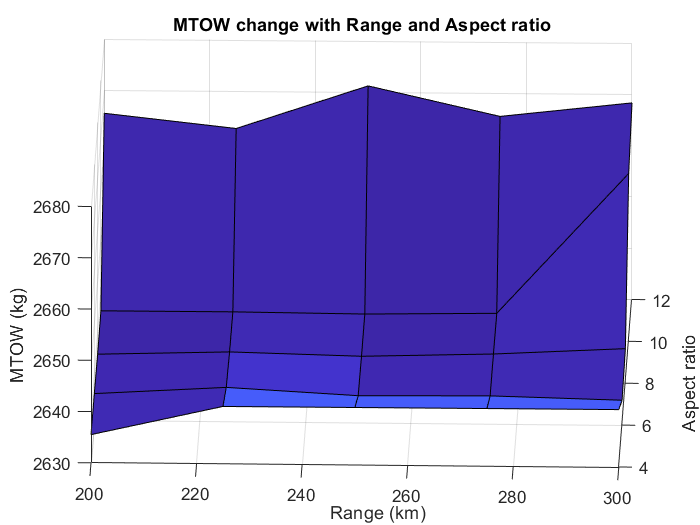

figure(1);
surf(var1,var2,MTOW);
title(strcat('MTOW change with',custom_title));
xlabel(xlegend);
ylabel(ylegend);
zlabel('MTOW (kg)');

## Wing loading

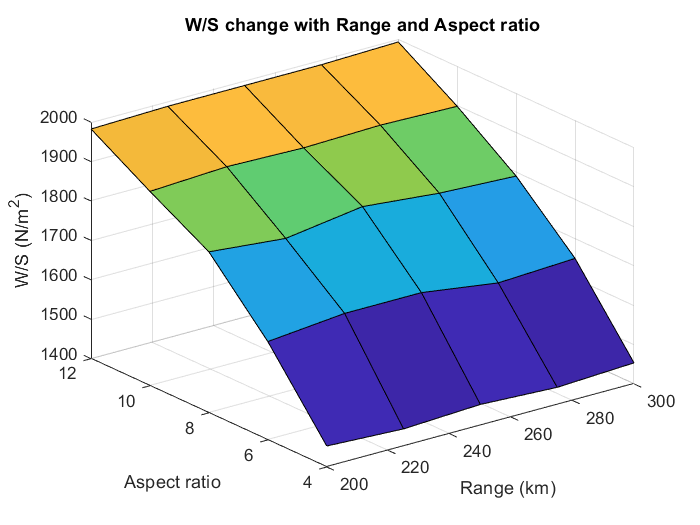

figure(2);
surf(var1,var2,WD);
title(strcat('W/S change with',custom_title));
xlabel(xlegend);
ylabel(ylegend);
zlabel('W/S (N/m^2)');

## Power loading foward

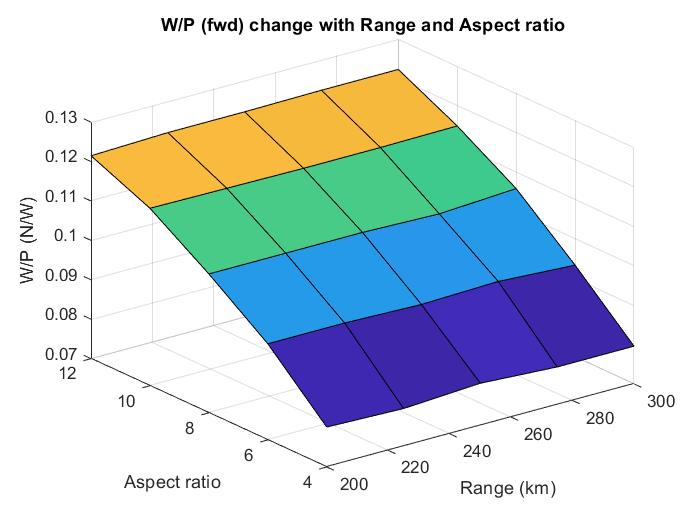

figure(3);
surf(var1,var2,PW_fwd);
title(strcat('W/P (fwd) change with',custom_title));
xlabel(xlegend);
ylabel(ylegend);
zlabel('W/P (N/W)');

## Power loading vertical

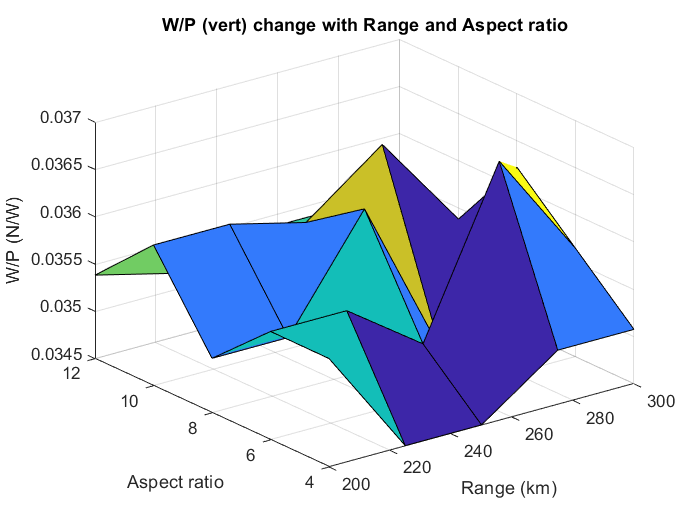

figure(4);
surf(var1,var2,PW_vert);
title(strcat('W/P (vert) change with',custom_title));
xlabel(xlegend);
ylabel(ylegend);
zlabel('W/P (N/W)');

## Disk loading

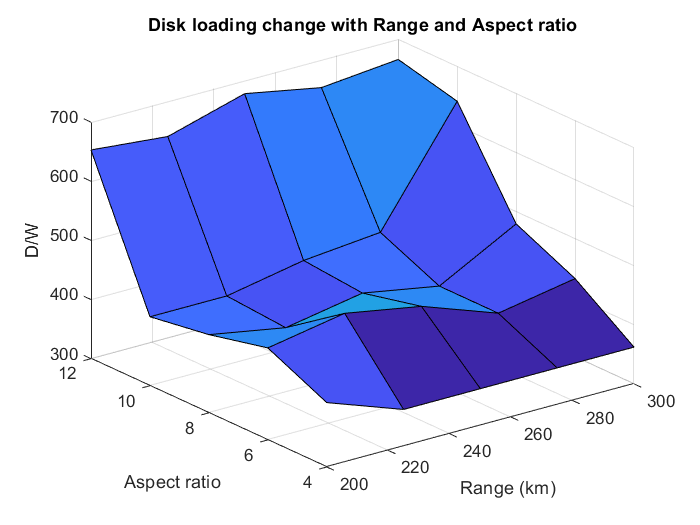

figure(5);
surf(var1,var2,DL);
title(strcat('Disk loading change with',custom_title));
xlabel(xlegend);
ylabel(ylegend);
zlabel('D/W');

## Power foward

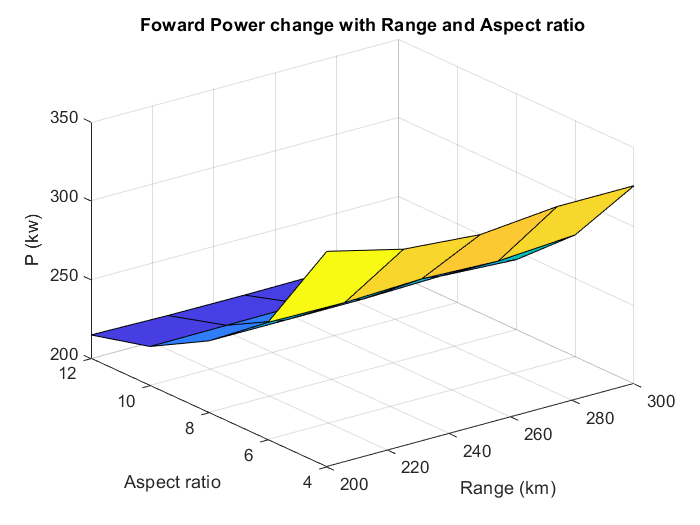

figure(6);
surf(var1,var2,P_fwd/1000);
title(strcat('Foward Power change with',custom_title));
xlabel(xlegend);
ylabel(ylegend);
zlabel('P (kw)');

## Power vert

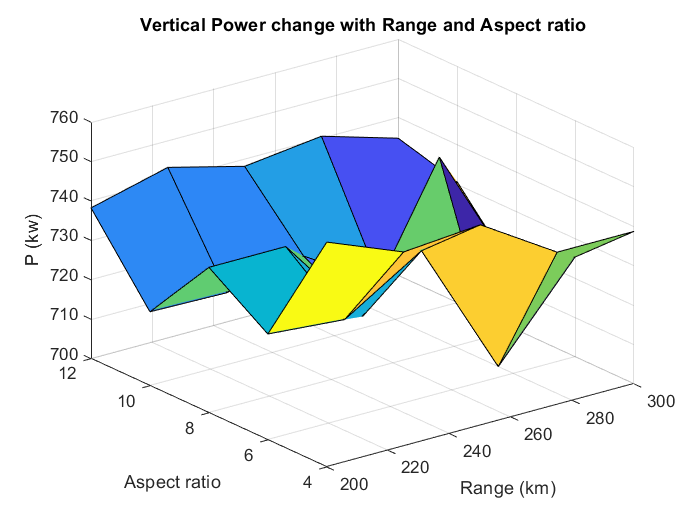

figure(7);
surf(var1,var2,P_vert/1000);
title(strcat('Vertical Power change with',custom_title));
xlabel(xlegend);
ylabel(ylegend);
zlabel('P (kw)');

## Span

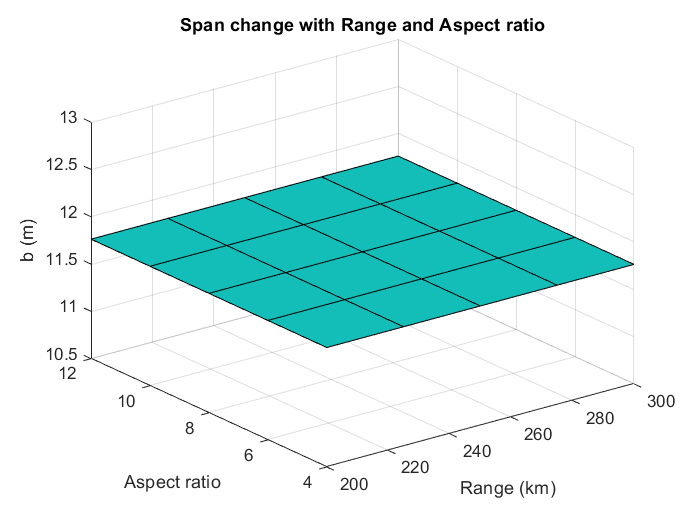

figure(8);
surf(var1,var2,span);
title(strcat('Span change with',custom_title));
xlabel(xlegend);
ylabel(ylegend);
zlabel('b (m)');

## Wing Area

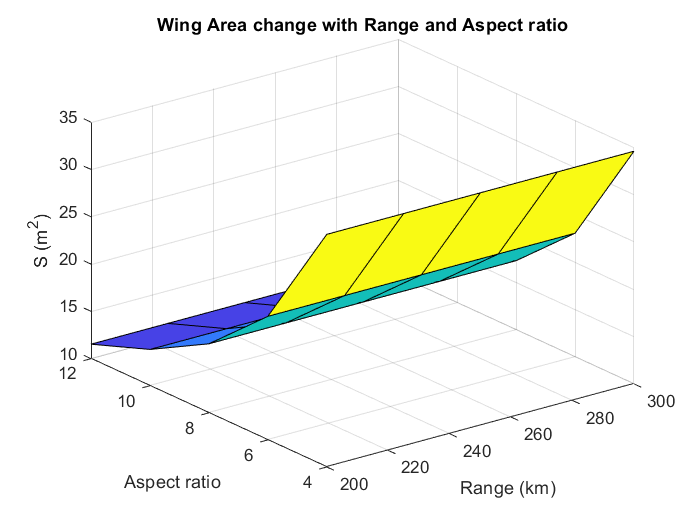

figure(9);
surf(var1,var2,S);
title(strcat('Wing Area change with',custom_title));
xlabel(xlegend);
ylabel(ylegend);
zlabel('S (m^2)');

## Mean chord

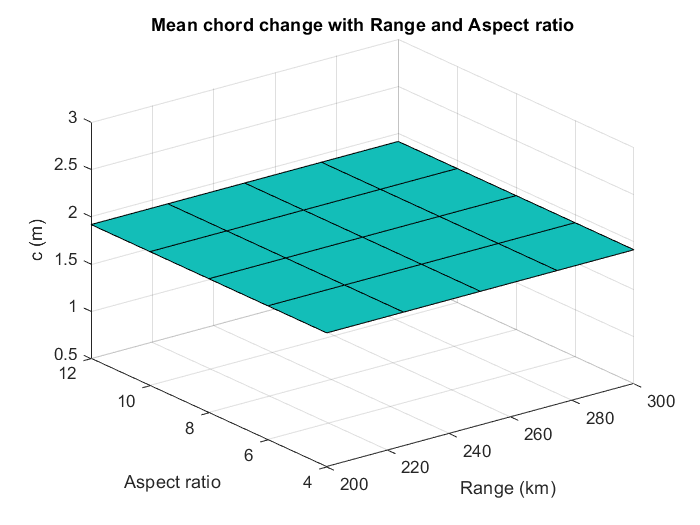

figure(10);
surf(var1,var2,c);
title(strcat('Mean chord change with',custom_title));
xlabel(xlegend);
ylabel(ylegend);
zlabel('c (m)');